%Pauli matrices
s1=sym([0 1;
        1 0]);

s2=sym([0 -1i;
        1i  0]);

s3=sym([1 0;
        0 -1]);

Pauli={s1,s2,s3};

**3.7 The Lorentz Group O(1,3)**

The Lorentz group is the set of all transformations that preserve

the inner product of Minkowski space


$$x^\mu x_\mu=x^\mu \eta_{\mu \nu} x^\nu =(x^0)^2-(x^1)^2-(x^2)^2-(x^3)^2$$


where


$$\eta_{\mu \nu}=\pmatrix{ 1 & 0 & 0 & 0 \cr 0 & -1 & 0 & 0 \cr 0 & 0 & -1 & 0 \cr 0 & 0 & 0 & -1}$$


minmet=diag([1 -1 -1 -1]);
minmetcov=diag([-1 1 1 1]);

Thus Lorentz transformation defined by


$$\Lambda^T \eta \Lambda = \eta$$


Since $\det{(\eta)}=-1$ and $\det{(AB)}=\det{(A)}\det{(B)}$ we conclude


$$\det{(\Lambda)}^2=1 \longrightarrow \det{(\Lambda)}=\pm 1$$


and from


$$\Lambda^\sigma_{\ 0} \eta_{\sigma \rho} \Lambda^\rho_{\ 0}=\eta_{00}$$


we get


$$\Lambda^0_0=\pm \sqrt{1+ \sum_i (\Lambda^i_0)^2$$


So we now have 4 categories of Lorentz transformation:


$$L^\uparrow_+ : det(\Lambda)=+1;\Lambda^0_0 \geq 1$$



$$L^\uparrow_- : det(\Lambda)=-1;\Lambda^0_0 \geq 1$$



$$L^\downarrow_+ : det(\Lambda)=+1;\Lambda^0_0 \leq -1$$



$$L^\downarrow_- : det(\Lambda)=-1;\Lambda^0_0 \leq -1$$


Only one of them includes the identity so we will focus on it since we can obtain others by time-reversal and space inversion operators where


$$\Lambda_{P}=\pmatrix{ 1 & 0 & 0 & 0 \cr 0 & -1 & 0 & 0 \cr 0 & 0 & -1 & 0 \cr 0 & 0 & 0 & -1}$$



$$\Lambda_{T}=\pmatrix{ -1 & 0 & 0 & 0 \cr 0 & 1 & 0 & 0 \cr 0 & 0 & 1 & 0 \cr 0 & 0 & 0 & 1}$$


LP=diag([1 -1 -1 -1])

LP =      1     0     0     0
     0    -1     0     0
     0     0    -1     0
     0     0     0    -1


LT=diag([-1 1 1 1])

LT =     -1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


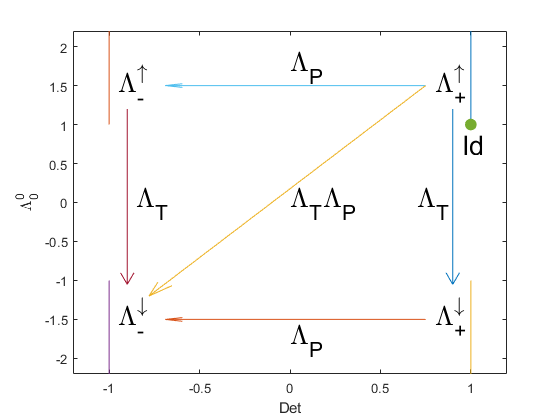



plot([1 1],[1 5])
hold on
plot([-1 -1],[1 5])
plot([1 1],[-1 -5])
plot([-1 -1],[-1 -5])

plot(1,1,'.','MarkerSize',30)

text(-.95,1.5,{'\Lambda^{\uparrow}_-'},'FontSize',20)
text(.8,1.5,{'\Lambda^{\uparrow}_+'},'FontSize',20)
text(.8,-1.5,{'\Lambda^{\downarrow}_+'},'FontSize',20)
text(-.95,-1.5,{'\Lambda^{\downarrow}_-'},'FontSize',20)
text(.95,.75,{'Id'},'FontSize',20)
quiver(.75,1.5,-1.6,0)
text(0,1.75,{'\Lambda_P'},'FontSize',20)
quiver(-.9,1.2,0,-2.5)
text(-.85,0,{'\Lambda_T'},'FontSize',20)
quiver(.9,1.2,0,-2.5)
text(.7,0,{'\Lambda_T'},'FontSize',20)
quiver(.75,-1.5,-1.6,0)
text(0,-1.75,{'\Lambda_P'},'FontSize',20)
quiver(.75,1.5,-1.7,-3)
text(0,0,{'\Lambda_T\Lambda_P'},'FontSize',20)

xlabel('Det')
ylabel('\Lambda^0_0')
axis([-1.2 1.2 -2.2 2.2])

hold off

4x4 matrices have 16 components but $\Lambda^T\eta \Lambda =\eta$ put 10 conditions on them so we actually have 6 parameters and thus 6 linearly independent generators. First note that the rotation matrices of 3-dimensional Euclidean space, which involve only space and leave the time unchanged, fulfil  the condition $\Lambda^T\eta \Lambda =\eta$. Thus,

$\Lambda_{rot}=\pmatrix{1 & \cr & R_{3x3}}$ and $J_i=\pmatrix{0 & \cr & J_i^{3dim}}$

%generators of rotation SO(3)
J1SO3=[0  0   0;
    0  0 -1i;
    0 1i   0];

J2SO3=[0  0 1i;
    0  0  0;
   -1i 0  0];

J3SO3=[0  -1i 0;
    1i  0  0;
    0   0  0];

%Lorentz spatial rotation generators
J1L=blkdiag(0,J1SO3);
J2L=blkdiag(0,J2SO3);
J3L=blkdiag(0,J3SO3);

To investigate transformations involving time and space we will start, as always in Lie theory, with an infinitesimal transformation.


$$\Lambda^\mu_{\rho} \approx \delta^\mu_{\rho} + \epsilon K^\mu_\rho$$


Putting this into the equation $\Lambda^T\eta \Lambda =\eta$ we obtain the condition


$$K^T\eta=-\eta K$$


For a boost along x axis the form of the generator is


$$K_{1}=\pmatrix{ a & b & 0 & 0 \cr c & d & 0 & 0 \cr 0 & 0 & 0 & 0 \cr 0 & 0 & 0 & 0}$$


syms kk [4 4]
minmet=diag([1 -1 -1 -1]);

eqn=transpose(kk)*minmet==-minmet*kk;
sol=solve(eqn,'ReturnCondition',true);
kk=[sol.kk1_1 sol.kk1_2 sol.kk1_3 sol.kk1_4;
    sol.kk2_1 sol.kk2_2 sol.kk2_3 sol.kk2_4;
    sol.kk3_1 sol.kk3_2 sol.kk3_3 sol.kk3_4;
    sol.kk4_1 sol.kk4_2 sol.kk4_3 sol.kk4_4;]

$$kk = \left(\begin{array}{cccc} 0 & z & z_{1} & z_{2}\\ z & 0 & -z_{3} & -z_{4}\\ z_{1} & z_{3} & 0 & -z_{5}\\ z_{2} & z_{4} & z_{5} & 0 \end{array}\right)$$

%there are 6 independent parameters so that 6 generators, we can choose every value we want for
%them we choose i for them the 3x3 matrix at the bottom right includes
%rotation generators
J1=subs(kk,sol.parameters,[zeros(1,5) 1i]);
J2=subs(kk,sol.parameters,[zeros(1,4) -1i 0]);
J3=subs(kk,sol.parameters,[zeros(1,3) 1i 0 0]);
J={J1,J2,J3};

K1=subs(kk,sol.parameters,[1i zeros(1,5)]);
K2=subs(kk,sol.parameters,[0 1i zeros(1,4)]);
K3=subs(kk,sol.parameters,[0 0 1i zeros(1,3)]);
K={K1, K2, K3};



$$M_{\mu\nu}=\pmatrix{0 & K_1 & K_2 & K_3 \cr -K_1 & 0 & J_3 & -J_2 \cr -K_2 & -J_3 &0&J_1 \cr -K_3 & J_2 & -J_1 & 0}$$


M4=Mmatrix(J1,J2,J3,K1,K2,K3);

for ii=1:4
    for jj=1:4
        for kk=1:4
            for ll=1:4
                cc=commutator(M4{ii,jj},M4{kk,ll});
                rr=1i*(minmetcov(ii,kk)*M4{jj,ll}-minmetcov(ii,ll)*M4{jj,kk}-minmetcov(jj,kk)*M4{ii,ll}+minmetcov(jj,ll)*M4{ii,kk});
                if ~isequal(cc,rr)
                    disp('fail')
                    break
                end
            end
        end
    end
    if ii==4 && jj==4 && kk==4 && ll==4
        disp('ok')
    end
end

ok



$$Lup \equiv \Lambda^\uparrow_+, \ \ Lum \equiv \Lambda^\uparrow_-, \ \ Ldp \equiv \Lambda^\downarrow_+, \ \ Ldm \equiv \Lambda^\downarrow_-$$


Lup={J1,J2,J3,K1,K2,K3};
Lum=cellfun(@(x) LP*x*transpose(LP),Lup,'UniformOutput',false);
Ldp=cellfun(@(x) LT*x*transpose(LT),Lup,'UniformOutput',false);
Ldm=cellfun(@(x) LT*LP*x*transpose(LP)*transpose(LT),Lup,'UniformOutput',false);


% Lorentz boost transformations for Lup
syms t
L1=simplify(expm(1i*t*K1))

$$L1 = \left(\begin{array}{cccc} \cosh\left(t\right) & -\sinh\left(t\right) & 0 & 0\\ -\sinh\left(t\right) & \cosh\left(t\right) & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

L2=simplify(expm(1i*t*K2))

$$L2 = \left(\begin{array}{cccc} \cosh\left(t\right) & 0 & -\sinh\left(t\right) & 0\\ 0 & 1 & 0 & 0\\ -\sinh\left(t\right) & 0 & \cosh\left(t\right) & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

L3=simplify(expm(1i*t*K3))

$$L3 = \left(\begin{array}{cccc} \cosh\left(t\right) & 0 & 0 & -\sinh\left(t\right)\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & 0\\ -\sinh\left(t\right) & 0 & 0 & \cosh\left(t\right) \end{array}\right)$$

commutator(L1,L2);


**3.7.3 The Lie Algebra of the Proper Orthochronous Lorentz Group**


$$[J_i,J_j]=i\epsilon_{ijk}J_k$$



$$[J_i,K_j]=i\epsilon_{ijk}K_k$$



$$[K_i,K_j]=-i\epsilon_{ijk}J_k$$


%constructing the commutators [Ji,Jj], [Ji,Kj]  and [Ki,Kj]
comcellj=cell(3);
comcelljk=cell(3);
comcellk=cell(3);

for ii=1:3
    for jj=1:3
        comcellj{ii,jj}=commutator(J{ii},J{jj});
        comcelljk{ii,jj}=commutator(J{ii},K{jj});
        comcellk{ii,jj}=commutator(K{ii},K{jj});
    end
end

%constructing the right half of the equations [Ji,Jj]=ieJk,...
iejkcell=cell(3);
iekcell=cell(3);
miejkcell=cell(3);

for ii=1:3
    for jj=1:3
       iejkcell{ii,jj}=1i*(levic(ii,jj,1)*J{1}+levic(ii,jj,2)*J{2}+levic(ii,jj,3)*J{3});
       iekcell{ii,jj}=1i*(levic(ii,jj,1)*K{1}+levic(ii,jj,2)*K{2}+levic(ii,jj,3)*K{3});
       miejkcell{ii,jj}=-1i*(levic(ii,jj,1)*J{1}+levic(ii,jj,2)*J{2}+levic(ii,jj,3)*J{3});
    end
end

%checking whether they are equal
isequal(comcellj,iejkcell)

ans = logical
   1


isequal(comcelljk,iekcell)

ans = logical
   1


isequal(comcellk,miejkcell)

ans = logical
   1


A general Lorentz transformation is of the form


$$\Lambda=e^{i\vec{J}\cdot\vec{\theta}+i\vec{K}\cdot\vec{\Phi}}$$


While the rotation generators are closed under commutation, the boost generators are not. We can now define two new operator types from the old ones that are closed under commutation and commute with each other.


$$N_i^{\pm}=\frac{1}{2}(J_i \pm iK_i)$$



$$[N_i^+,N_j^+]=i\epsilon_{ijk}N_k^+$$



$$[N_i^-,N_j^-]=i\epsilon_{ijk}N_k^-$$



$$[N_i^+,N_j^-]=0$$


Np=cellfun(@(x,y) 1/2*(x+1i*y),J,K,'UniformOutput',false);
Nm=cellfun(@(x,y) 1/2*(x-1i*y),J,K,'UniformOutput',false);

%commutators of Ns
comcellNp=cell(3);
comcellNm=cell(3);
comcellNpm=cell(3);

for ii=1:3
    for jj=1:3
        comcellNp{ii,jj}=commutator(Np{ii},Np{jj});
        comcellNm{ii,jj}=commutator(Nm{ii},Nm{jj});
        comcellNpm{ii,jj}=commutator(Np{ii},Nm{jj});
    end
end


%right half of the equations
ieNkpcell=cell(3);
ieNkmcell=cell(3);
ieNkpmcell=cell(3);
ieNkpmcell(:)={sym(zeros(4,4))};

for ii=1:3
    for jj=1:3
       ieNkpcell{ii,jj}=1i*(levic(ii,jj,1)*Np{1}+levic(ii,jj,2)*Np{2}+levic(ii,jj,3)*Np{3});
       ieNkmcell{ii,jj}=1i*(levic(ii,jj,1)*Nm{1}+levic(ii,jj,2)*Nm{2}+levic(ii,jj,3)*Nm{3});
    end
end

%cheching the relations
isequal(comcellNp,ieNkpcell)

ans = logical
   1


isequal(comcellNm,ieNkmcell)

ans = logical
   1


isequal(comcellNpm,ieNkpmcell)

ans = logical
   1


These are precisely the commutation relations for the Lie algebra of $SU(2)$ and we have therefore discovered that the complexified Liealgebra of $L^\uparrow_+$ consists of two copies of the Lie algebra $su(2)$. The above 4-vector representation is the $(\frac{1}{2},\frac{1}{2})$ representation. But there are different representations.

It is conventional to write the Lorentz algebra in a more compact way by introducing a new symbol $M_{\mu \nu}$, which is defined through the equations


$$J_i=\frac{1}{2}\epsilon_{ijk}M_{jk}$$



$$K_i=M_{0i}$$


With this new definition the Lorentz algebra reads


$$[M_{\mu\nu},M_{\rho\sigma}]=i(\eta_{\mu\rho}M_{\nu\sigma}-\eta_{\mu\sigma}M_{\nu\rho}-\eta_{\nu\rho}M_{\mu\sigma}+\eta_{\nu\sigma}M_{\mu\rho})$$


**3.7.5 The **$(0, 0)$** Representation**


$$N_i^+ \rightarrow j=0$$



$$N_i^- \rightarrow j=0$$


Np0=su2rep(0);
Nm0=su2rep(0);

Since $N_i^{\pm}=\frac{1}{2}(J_i \pm iK_i)$:

J00=cellfun(@(x,y) x+y,Np0,Nm0,'UniformOutput',false);
K00=cellfun(@(x,y) (x-y)/1i,Np0,Nm0,'UniformOutput',false);

syms t
Rx00=simplify(expm(1i*t*J00{1}))

$$Rx00 = 1$$

**3.7.5 The **$(\frac{1}{2}, 0)$** Representation**


$$N_i^+ \rightarrow j=\frac{1}{2}$$



$$N_i^- \rightarrow j=0$$


Np12=su2rep(1/2);
Nm0=su2rep(0);

Since $N_i^{\pm}=\frac{1}{2}(J_i \pm iK_i)$

J120=cellfun(@(x,y) x+y,Np12,Nm0,'UniformOutput',false);
K120=cellfun(@(x,y) (x-y)/1i,Np12,Nm0,'UniformOutput',false);
%an example of rotation around x axis

Here, we have found that $J_i=\frac{1}{2}\sigma_i$ and $K_i=\frac{-1}{2}\sigma_i$ 

cellfun(@(x,y) isequal(x,1/2*y),J120,Pauli)

ans = 1×3 logical array
   1   1   1


cellfun(@(x,y) isequal(x,-1i/2*y),K120,Pauli)

ans = 1×3 logical array
   1   1   1


We know that a Lorentz transformation is given by $\Lambda=e^{i\vec{J}\cdot\vec{\theta}+i\vec{K}\cdot\vec{\Phi}}$ which has 2 parts $e^{i\vec{J}\cdot\vec{\theta}}$ yields rotations while $e^{i\vec{K}\cdot\vec{\Phi}}$ yields boosts where


$$R_\theta=e^{i\vec{J}\cdot\vec{\theta}}=e^{i\vec{\frac{\sigma}{2}}\cdot\vec{\theta}}$$



$$B_\Phi=e^{i\vec{K}\cdot\vec{\Phi}}=e^{\vec{\frac{\sigma}{2}}\cdot\vec{\Phi}}$$


syms t p real
R120={simplify(expm(1i*t*J120{1})),simplify(expm(1i*t*J120{2})),simplify(expm(1i*t*J120{3}))};
B120={simplify(expm(1i*t*K120{1})), simplify(expm(1i*t*K120{2})), simplify(expm(1i*t*K120{3}))};
T120=[R120,B120];

One important thing to notice is that we have here complex 2 × 2 matrices, representing the Lorentz transformations. These transformations certainly do not act on the four-vectors of Minkowski space, because these have 4 components. The two-component objects this representation acts on are called left-chiral spinors:


$$\chi_L=\pmatrix{(\chi_L)_1 \cr (\chi_L)_2 }$$


Spinors in this context are two component objects. A possible definition for **left-chiral spinors** is that they are objects that transform under Lorentz transformations according to the $(\frac{1}{2}, 0)$ representation of the Lorentz group. Take note that this is not just another way to describe the same thing, because spinors have properties that usual vectors do not have. For instance, the factor $\frac{1}{2}$ in the exponent. This factor shows us that a spinor is after a rotation by $2\pi$ not the same, but gets a minus sign. This is a pretty crazy property, because we usually expect that objects are exactly the same after a rotation by $2\pi$.

". . . a spinor is the most basic sort of mathematical object that can be Lorentz-transformed." 

-**A. M. Steane**

**3.7.5 The **$(0,\frac{1}{2})$** Representation**


$$N_i^+ \rightarrow j=0$$



$$N_i^- \rightarrow j=\frac{1}{2}$$


Np0=su2rep(0);
Nm12=su2rep(1/2);

Since $N_i^{\pm}=\frac{1}{2}(J_i \pm iK_i)$

J012=cellfun(@(x,y) x+y,Np0,Nm12,'UniformOutput',false);
K012=cellfun(@(x,y) (x-y)/1i,Np0,Nm12,'UniformOutput',false);



$$J_i=\frac{1}{2}\sigma_i$$



$$K_i=-\frac{1}{2}\sigma_i$$


cellfun(@(x,y) isequal(x,1/2*y),J012,Pauli)

ans = 1×3 logical array
   1   1   1


cellfun(@(x,y) isequal(x,1i/2*y),K012,Pauli)

ans = 1×3 logical array
   1   1   1



$$R_\theta=e^{i\vec{J}\cdot\vec{\theta}}=e^{i\vec{\frac{\sigma}{2}}\cdot\vec{\theta}}$$



$$B_\Phi=e^{i\vec{K}\cdot\vec{\Phi}}=e^{-\vec{\frac{\sigma}{2}}\cdot\vec{\Phi}}$$



syms t real
R012={simplify(expm(1i*t*J012{1})),simplify(expm(1i*t*J012{2})),simplify(expm(1i*t*J012{3}))};
B012={simplify(expm(1i*t*K012{1})),simplify(expm(1i*t*K012{2})),simplify(expm(1i*t*K012{3}))};
T012=[R012,B012];

Therefore, rotations are the same as in the $(\frac{1}{2}, 0)$ representation, but boosts differ by a minus sign in the exponent. We conclude both representations act on objects that are **similar but not the same**. We call the objects the $(0,\frac{1}{2})$representation of the Lorentz group acts on **right-chiral spinors**:


$$\chi_R=\pmatrix{(\chi_R)_1 \cr (\chi_R)_2 }$$


The generic name for left- and right-chiral spinors is **Weyl spinors**.

# **3.7.7 Van der Waerden Notation**

Let’s define that a left-chiral spinor χL has a lower, undotted index

#### 
$$\chi_L = \chi_a$$


syms XL [2 1]
XL

$$XL = \left(\begin{array}{c} {\mathrm{XL}}_{1}\\ {\mathrm{XL}}_{2} \end{array}\right)$$

and a right-chiral spinor $\chi_R=\chi^{\dot{a}}$ has an upper, dotted index. Next, we introduce the "spinor metric". The spinor metric enables us to transform a right-chiral spinor into a left-chiral and vice versa but not alone as we will see. We define the spinor metric as

#### 
$$\epsilon^{ab}=\pmatrix{0&1\cr-1&0}$$


#### 
$$\epsilon_{ab}=\pmatrix{0&-1\cr1&0}=-\epsilon^{ab}$$


e=[0 1;-1 0];

and show that it has the desired properties. Furthermore, we define

#### 
$$\chi_L^C \equiv \epsilon \chi_L^*$$


where * denotes complex conjugation. Let us have a look at how $\chi_L^C$

transforms under boosts, where we use


$$(-\epsilon)(\epsilon)=1$$


-e*e

ans =      1     0
     0     1


and 


$$(\epsilon)\sigma_i^*(-\epsilon)=-\sigma_i$$


cellfun(@(x) isequal((e*conj(x)*-e),-x),Pauli)

ans = 1×3 logical array
   1   1   1


#### Transforming $\chi_L^C$ where $\chi_L^C \equiv \epsilon \chi_L^*$ yields

#### 
$$(\chi_L^C)'=\epsilon(\chi_L^{'})*$$


####             
$$=\epsilon(e^{i\theta \cdot J_{120}+i\Phi \cdot K_{120}} \chi_L)^*$$


####             
$$=e^{i\theta \cdot J_{012}+i\Phi \cdot K_{012}} \chi_L^C$$


%definition of XLC
XLC=e*conj(XL);

%transformations of left chiral
XLn=cellfun(@(x) x*XL,T120,'UniformOutput',false);

%transformations of XLC with the above equation
XLCn=cellfun(@(x) e*conj(x),XLn,'UniformOutput',false);

%transformations of XLC as right chiral
XLCnR=cellfun(@(x) x*XLC,T012,'UniformOutput',false);

%both are equal so XLC is a right chiral
cellfun(@(x,y) isequal(x,y),XLCn,XLCnR)

ans = 1×6 logical array
   1   1   1   1   1   1


We define in analogy with the tensor notation of special relativity that our "metric" raises and lowers indices

#### 
$$\epsilon \chi_L = \epsilon^{ac}\chi_c =\chi^a$$


e*XL

$$ans = \left(\begin{array}{c} {\mathrm{XL}}_{2}\\ -{\mathrm{XL}}_{1} \end{array}\right)$$

Furthermore, we know that if we want to get $\chi_R$ from $\chi_L$ we need to use complex conjugation as well

#### 
$$\chi_R=\epsilon \chi_L^*$$


XR=e*conj(XL)

$$XR = \left(\begin{array}{c} \bar{{\mathrm{XL}}_{2}}\\ -\bar{{\mathrm{XL}}_{1}} \end{array}\right)$$

This means that complex conjugation transforms an undotted index into a dotted index:

#### 
$$\chi_R=\epsilon \chi_L^* =\chi^{\dot{a}}$$


Therefore, we can get a lower, dotted index by complex conjugating $\chi_L$:

#### 
$$\chi_L^*=\chi_a^*=\chi_{\dot{a}}$$


and an upper, undotted index, by complex conjugating $\chi_R$

#### 
$$\chi_R^*=(\chi^{\dot{a}})^*=\chi^a$$


Xdowna=XL

$$Xdowna = \left(\begin{array}{c} {\mathrm{XL}}_{1}\\ {\mathrm{XL}}_{2} \end{array}\right)$$

Xdowndota=conj(XL)

$$Xdowndota = \left(\begin{array}{c} \bar{{\mathrm{XL}}_{1}}\\ \bar{{\mathrm{XL}}_{2}} \end{array}\right)$$

Xupa=conj(XR)

$$Xupa = \left(\begin{array}{c} {\mathrm{XL}}_{2}\\ -{\mathrm{XL}}_{1} \end{array}\right)$$

Xupdota=XR

$$Xupdota = \left(\begin{array}{c} \bar{{\mathrm{XL}}_{2}}\\ -\bar{{\mathrm{XL}}_{1}} \end{array}\right)$$

%Lorentz invariant terms are
XR'*XL

$$ans = 0$$

XL'*XR

$$ans = 0$$

#### 
$$\chi_R^{'}=\chi^{'\dot{a}}=\Lambda^{\dot{a}}_{\ \dot{b}}\chi^{\dot{b}}=(e^{i\vec{\theta}\frac{\vec{\sigma}}{2}-\vec{\Phi}\frac{\vec{\sigma}}{2}})^{\dot{a}}_{\ \dot{b}}\chi^{\dot{b}}$$


#### 
$$\chi_L^{'}=\chi^{'}_a=\Lambda_a^{\ b}\chi_b=(e^{i\vec{\theta}\frac{\vec{\sigma}}{2}+\vec{\Phi}\frac{\vec{\sigma}}{2}})^{\ b}_{a}\chi_b$$


TXdowna=T120;
TXupdota=T012;
TXdowndota=cellfun(@(x) conj(x),TXdowna,'UniformOutput',false);
TXupa=cellfun(@(x) conj(x),TXupdota,'UniformOutput',false);

#### **3.7.8 The **$(\frac{1}{2},\frac{1}{2})$** Representation**

For this representation we use the 2-dimensional representation for both copies of the $SU(2)$ Lie algebra $N_i^+$ and $N_i^-$


$$v=v_{a\dot{b}}=(v_\nu \sigma^\nu)_{a\dot{b}}$$


            
$$=v_0\pmatrix{1 & 0 \cr 0 &1}+ v_1 \pmatrix{0& 1 \cr 1& 0} + v_2 \pmatrix{0& -i \cr i& 0}+ v_3 \pmatrix{1& 0 \cr 0& -1}$$


            
$$=\pmatrix{v_0+v_3 & v_1-iv_2 \cr v_1+iv_2 & v_0-v_3}$$


**3.7.9 Spinors and Parity**

isequal(LP*J1*transpose(LP),J1)

ans = logical
   1


isequal(LP*K1*transpose(LP),-K1)

ans = logical
   1


Npparity=cellfun(@(x) LP(1:2,1:2)*x*transpose(LP(1:2,1:2)),K120,'UniformOutput',false)

Npparity = 1×3 cell array
    {2×2 sym}    {2×2 sym}    {2×2 sym}


syms XL YR [2 1]

%Dirac spinor
D=[XL;YR]

$$D = \left(\begin{array}{c} {\mathrm{XL}}_{1}\\ {\mathrm{XL}}_{2}\\ {\mathrm{YR}}_{1}\\ {\mathrm{YR}}_{2} \end{array}\right)$$

Tdirac=cellfun(@(x,y) blkdiag(x,y),T120,T012,'UniformOutput',false);
%a boost transformation example
TransD=Tdirac{4}*D

$$TransD = \left(\begin{array}{c} {\mathrm{XL}}_{1}\,\cosh\left(\frac{t}{2}\right)+{\mathrm{XL}}_{2}\,\sinh\left(\frac{t}{2}\right)\\ {\mathrm{XL}}_{2}\,\cosh\left(\frac{t}{2}\right)+{\mathrm{XL}}_{1}\,\sinh\left(\frac{t}{2}\right)\\ {\mathrm{YR}}_{1}\,\cosh\left(\frac{t}{2}\right)-{\mathrm{YR}}_{2}\,\sinh\left(\frac{t}{2}\right)\\ {\mathrm{YR}}_{2}\,\cosh\left(\frac{t}{2}\right)-{\mathrm{YR}}_{1}\,\sinh\left(\frac{t}{2}\right) \end{array}\right)$$

%Infinite dimensional representation

If our object $\Phi$ changes in space and time, it is a function of coordinates $\Phi=\Phi(x)$ and these coordinates are affected by the Lorentz transformations, too.

#### 
$$M^{inf}_{\mu\nu}=i(x^\mu\partial^\nu-x^\nu\partial^\mu)$$



$$\omega_{\mu\nu}=\pmatrix{0 & \Phi_1 & \Phi_2 & \Phi_3 \cr -\Phi_1 & 0 & \theta_3 & -\theta_2 \cr -\Phi_2 & -\theta_3 &0&\theta_1 \cr -\Phi_3 & \theta_2 & -\theta_1 & 0}$$


The transformation of the coordinates is now given by

#### 
$$\Phi^{'}(\Lambda x)=e^{-i \ \frac{\omega^{\mu \nu}}{2}M^{inf}_{\mu\nu}}\Phi(x)$$


The complete transformation is then a combination of a transformation generated by the finite-dimensional representation $M^{fin}_{\mu \nu }$ and a transformation generated by the infinitedimensional representation $M^{inf}_{\mu\nu}$ of the generators:


$$\Phi_a(x) \rightarrow (e^{-i \ \frac{\omega^{\mu \nu}}{2}M^{inf}_{\mu\nu}})^a_b \ e^{-i \ \frac{\omega^{\mu \nu}}{2}M^{inf}_{\mu\nu}}\Phi_b(x)$$


This represenatation of the generators of the Lorentz group is called field representation.

Translation:

An infinitesimal translation of a function is given by


$$\Phi(x) \rightarrow \Phi(x_i+\epsilon)=\Phi(x)+\partial_x \Phi(x)\epsilon$$


It is conventional in physics to add an extra $-i$ to the generator and we therefore define


$$P_i \equiv -i\partial_i$$


**3.8 The Poincaré Group**

Poincaré group = Lorentz group **plus** translations 

                         = Rotations **plus** boosts **plus** translations

With $M\mu \nu $ the Poincaré algebra reads:


$$[P_\mu,P_\nu]=0$$



$$[M_{\mu\nu},P\rho]=i(\eta_{\mu\rho}P_\nu-\eta_{\nu\rho}P_\mu)$$



$$[M_{\mu\nu},M_{\rho\sigma}]=i(\eta_{\mu\rho}M_{\nu\sigma}-\eta_{\mu\sigma}M_{\nu\rho}-\eta_{\nu\rho}M_{\mu\sigma}+\eta_{\nu\sigma}M_{\mu\rho})$$


• spin $0$ is described by an object $\Phi$, called scalar, that transforms according to the $(0, 0)$, called spin $0$ representation or scalar representation.

For example, the Higgs particle is described by a scalar field.

• spin $\frac{1}{2}$ is described by an object $\Psi$, called spinor, that transforms according to the $(\frac{1}{2}, 0) \oplus  (0, \frac{1}{2})$ representation, called spin $\frac{1}{2}$ representation or spinor representation.

 For example, electrons and quarks are described by spinors.

• spin $1$ is described by an object $A$, called vector, that transforms according to the $(\frac{1}{2}, \frac{1}{2})$ called spin $1$ representation or vector representation.

 For example photons are described by vectors

Levi civita

function c=levic(a,b,c)
    if nargin>3 || nargin<2
        error('2 or 3 arguments are needed')
    elseif nargin==2 && (a<1 || a>2 || b<1 || b>2)
        error('arguments must be 1 or 2')
    elseif nargin==3 && (a<1 || a>3 || b<1 || b>3 || c<1 || c>3)
        error('arguments must be 1, 2 or 3')
    end

    switch nargin
        case 2
            if (a==1 && b==2)
                c=1;
            elseif (a==2 && b==1)
                c=-1;
            else
                c=0;
            end
        case 3
            if (a==1 && b==2 && c==3) || (a==2 && b==3 && c==1) || (a==3 && b==1 && c==2)
                c=1;
            elseif (a==1 && b==3 && c==2) || (a==2 && b==1 && c==3) || (a==3 && b==2 && c==1)
                c=-1;
            else
                c=0;
            end
    end
end


%commutator
function res=commutator(X,Y)
    res=X*Y-Y*X;
end


%Every finite dimensional representation of SU(2)
%the only variable is j, others follow it

%2j+1 gives the dimension e.g. for 2D j=1/2

function [generators,label]=su2rep(j)
    %m is the eigenvalues of J3 and starts with the maximum eigenvalue
    j=sym(j);
    m=j:-1:-j;
    
    %J+ |b,m> = Cp |b,m+1> 
    Cp=sqrt(j*(j+1)-m.^2-m);
    
    %J- |b,m> = Cm |b,m-1> 
    Cm=sqrt(j*(j+1)-m.^2+m);
    
    %representation label
    b=j*(j+1);
    %J3 is diagonal and the values are m
    J3=diag(m);
    %eigenvectors of J3
    evec=eye(length(J3));
    %this is a little tricky, J+ moves the columns of evec to the right
    % and multiply each colum with Cp
    
    el=length(evec);
    
    %evec(:,[el 1:(el-1)]) gives evec with permuted to right
    Jp=(evec(:,[el 1:(el-1)])*diag(Cp))*inv(evec);
    %evec(:,[2:el 1]) gives evec with permuted to left
    Jm=(evec(:,[2:el 1])*diag(Cm))*inv(evec);
    %J1=1/2(J+ + J-) by definition
    J1=1/2*(Jp+Jm);
    %J1=1/2(J- - J+) by definition
    J2=1i/2*(Jm-Jp);
    generators={J1,J2,J3};
    label=j;
end

function M=Mmatrix(J1,J2,J3,K1,K2,K3)
    M=cell(4);
    M(:)={sym(zeros(length(J1)))};
    
    M{1,2}=K1; M{2,1}=-K1;    
    M{1,3}=K2; M{3,1}=-K2;
    M{1,4}=K3; M{4,1}=-K3;
    
    M{3,4}=J1; M{4,3}=-J1;
    M{4,2}=J2; M{2,4}=-J2;
    M{2,3}=J3; M{3,2}=-J3;
    
end